clc,clear

% 加载数据，绘制时间序列图，
t = [1976:1987];
yt = load('dianqi.txt')        %原始数据以列向量的方式存放在纯文本文件中

yt =     50    52    47    51    49    48    51    40    48    52    51    59


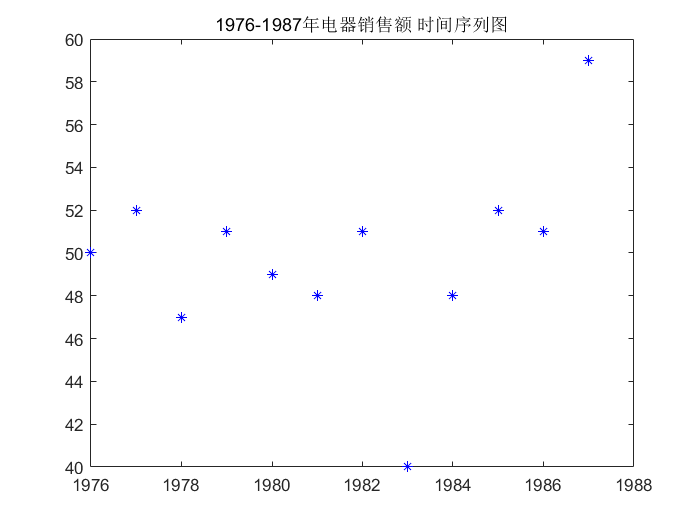


figure(1)
plot(t,yt,'b*');
set(get(gca, 'Title'), 'String', '1976-1987年电器销售额 时间序列图');

%计算数据的长度(个数)
n=length(yt)

n = 12

%不同的加权系数
alpha=[0.2 0.5 0.8]

alpha =     0.2000    0.5000    0.8000


%不同的加权系数的个数   对于不同的加权个数，进行不同预测
m=length(alpha);
%初值 对于少于20个数据，一般选择最初几期实际值的平均值作为初始值
yhat(1,1:m)=(yt(1)+yt(2))/2

yhat =     51    51    51


for i=2:n
    yhat(i,:)=alpha*yt(i-1)+(1-alpha).*yhat(i-1,:);
end
yhat   %一次指数平滑预测值

yhat =    51.0000   51.0000   51.0000
   50.8000   50.5000   50.2000
   51.0400   51.2500   51.6400
   50.2320   49.1250   47.9280
   50.3856   50.0625   50.3856
   50.1085   49.5313   49.2771
   49.6868   48.7656   48.2554
   49.9494   49.8828   50.4511
   47.9595   44.9414   42.0902
   47.9676   46.4707   46.8180






%把数据写入到excel文件中
xlswrite('dianqi.xls',yhat)

%预测1988年的销售额
yhat1988=alpha*yt(n)+(1-alpha).*yhat(n,:)   

yhat1988 =    51.1754   54.5588   57.3985
